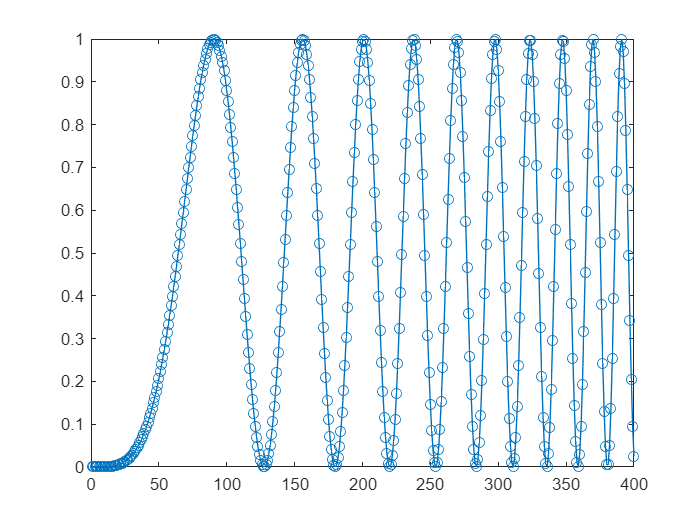

hchirp = dsp.Chirp( ...
    'InitialFrequency', 0,...
    'TargetFrequency', 2, ...
    'TargetTime', 10, ...
    'SweepTime', 400, ...
    'SampleRate', 40, ...
    'SamplesPerFrame', 400, ...
    'InitialPhase', pi);

chirpData = ((step(hchirp))'/2)+0.5;
% evenFlag = mod(minute(datetime('now')),2);
% if evenFlag
%     chirpData = fliplr(chirpData);
% end

plot(chirpData, '-o');


u = int16(round(chirpData*4096))

u = 1×400 int16 row vector
     0     0     0     0     0     0     0     0     1     1     2     2     3     5     6     8    10    13    17    21    25    31    37    44    52    61    72    83    96   111   127   144   163   184   207   232   260   289   321   355   391   430   472   517   564   614   667   723   783   845


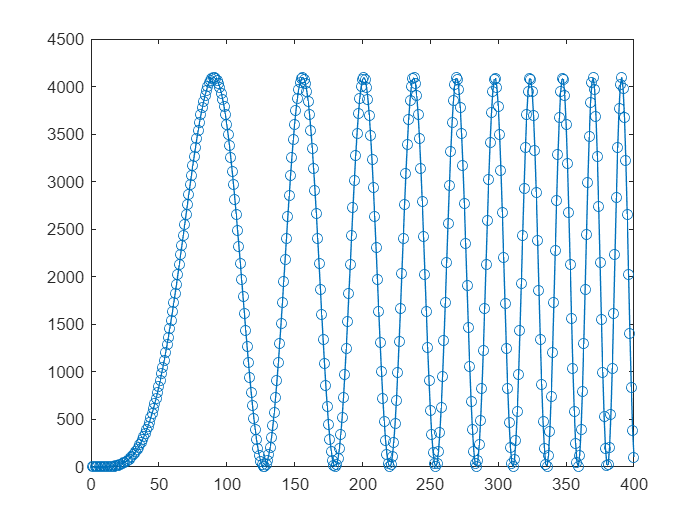


plot(u, '-o');